data = struct with fields:
           A: [5×5 double]
           B: [5×3 double]
           C: [2×5 double]
           D: [2×3 double]
         FWT: [2×3 ss]
    WindData: [60001×2 double]


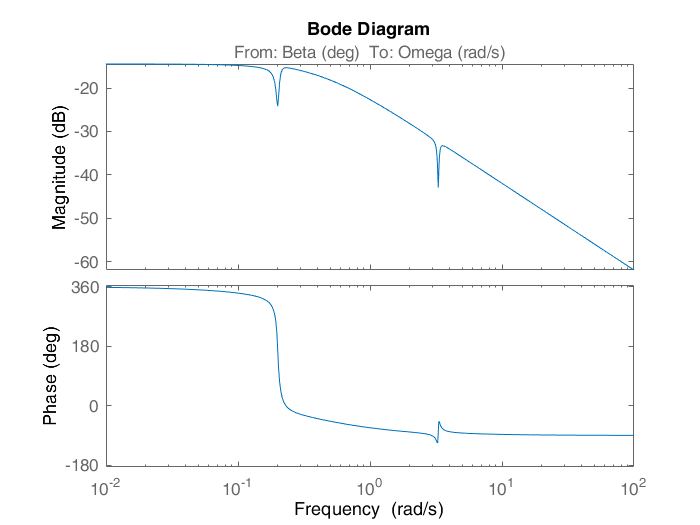

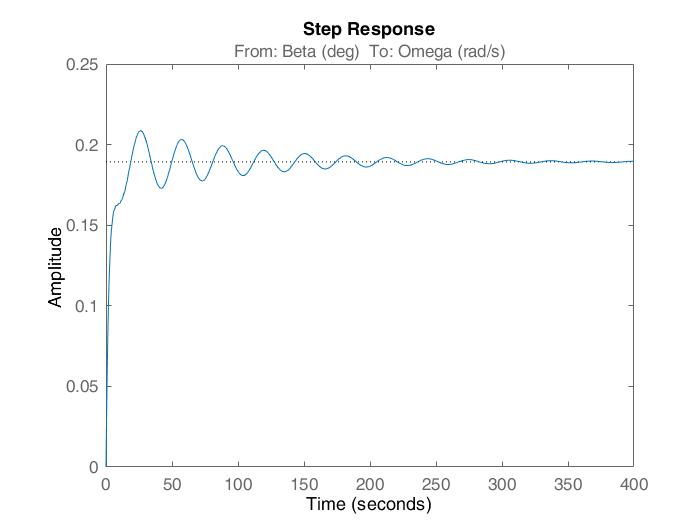

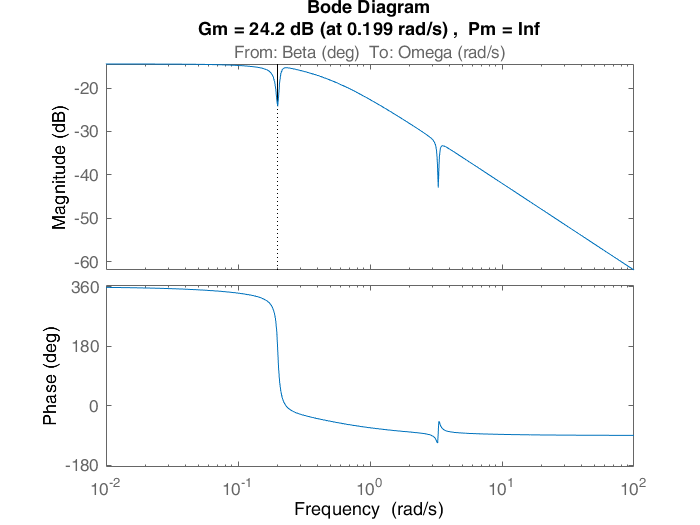

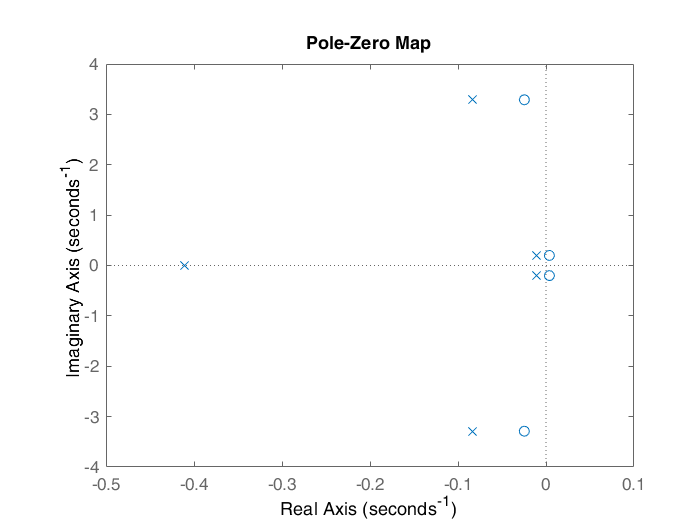

ans = struct with fields:
        RiseTime: 13.6517
    SettlingTime: 168.7029
     SettlingMin: 0.1704
     SettlingMax: 0.2086
       Overshoot: 10.2142
      Undershoot: 0
            Peak: 0.2086
        PeakTime: 26.4813


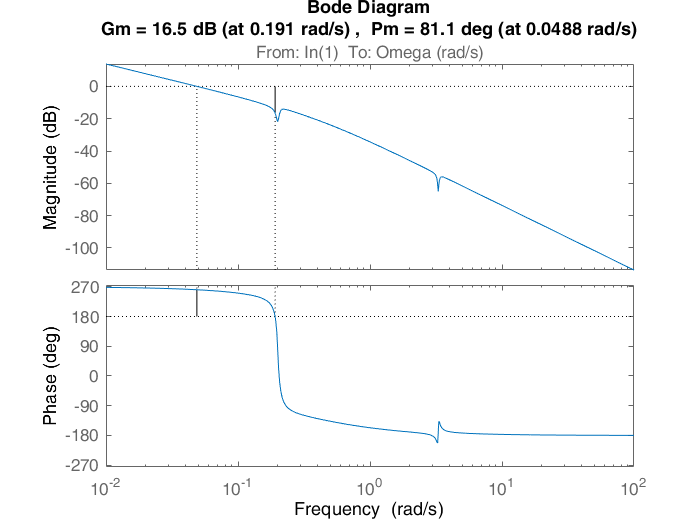

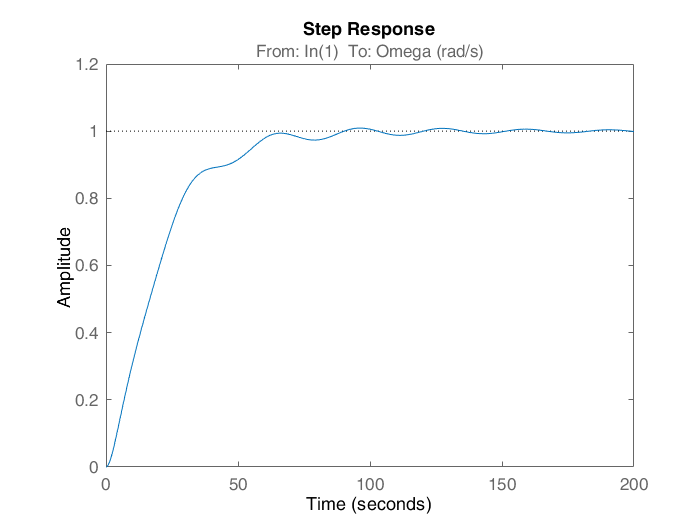

ans = struct with fields:
        RiseTime: 41.9600
    SettlingTime: 83.7071
     SettlingMin: 0.9003
     SettlingMax: 1.0092
       Overshoot: 0.9190
      Undershoot: 0
            Peak: 1.0092
        PeakTime: 96.0803


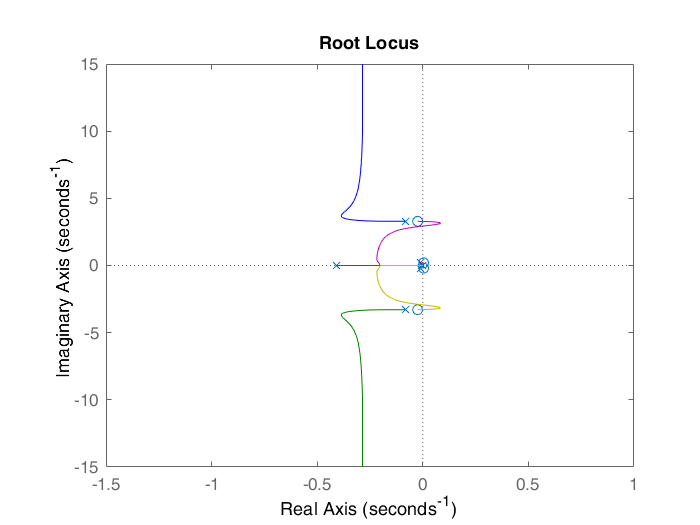

data = importdata("Assignment_Data_SC42145_2022.mat")

FWT=data.FWT;

% 1.1 
bode(-FWT(1,1))
step(-FWT(1,1))
margin(-FWT(1,1))
pzmap(-FWT(1,1));
A =zero(-FWT(1,1));
stepinfo(-FWT(1,1))

% 1.3
s = tf('s');
Plant = -FWT(1,1);

% PID weights
Kp = 0;
Ki = 0.26;
Kd = 0;
Tf=0;
K = pid(Kp, Ki, Kd);

PoleCancel = minreal(Plant*K);
margin(PoleCancel)
sys_cl = feedback(PoleCancel,1);

% Step response and other system specificiations
[y,t] = step(sys_cl);
step(sys_cl)
stepinfo(sys_cl)
rlocus(PoleCancel)
